A file that calculates the required delta V's for a given Hohmann transfer 

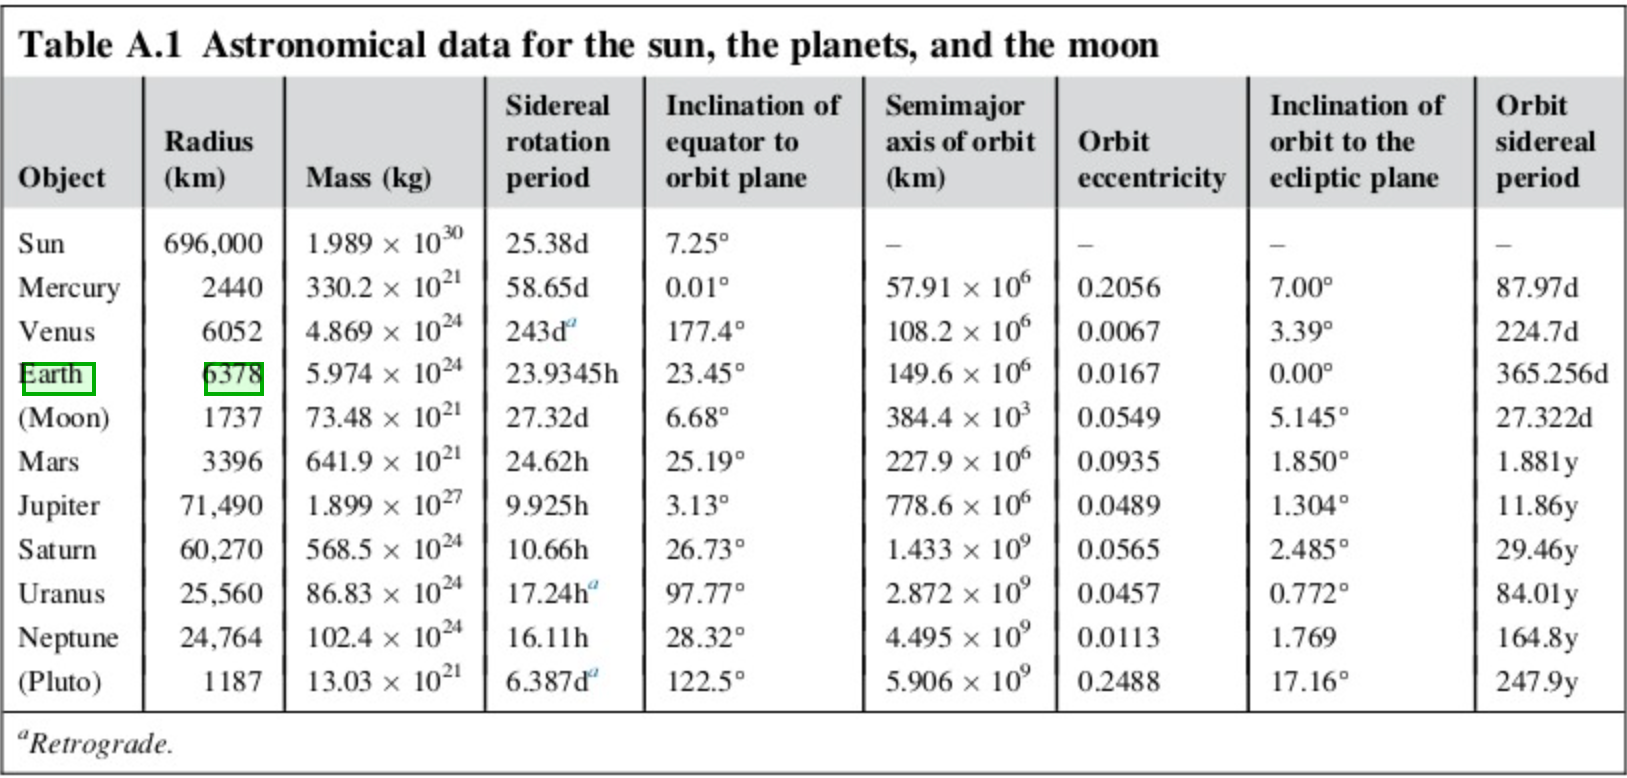

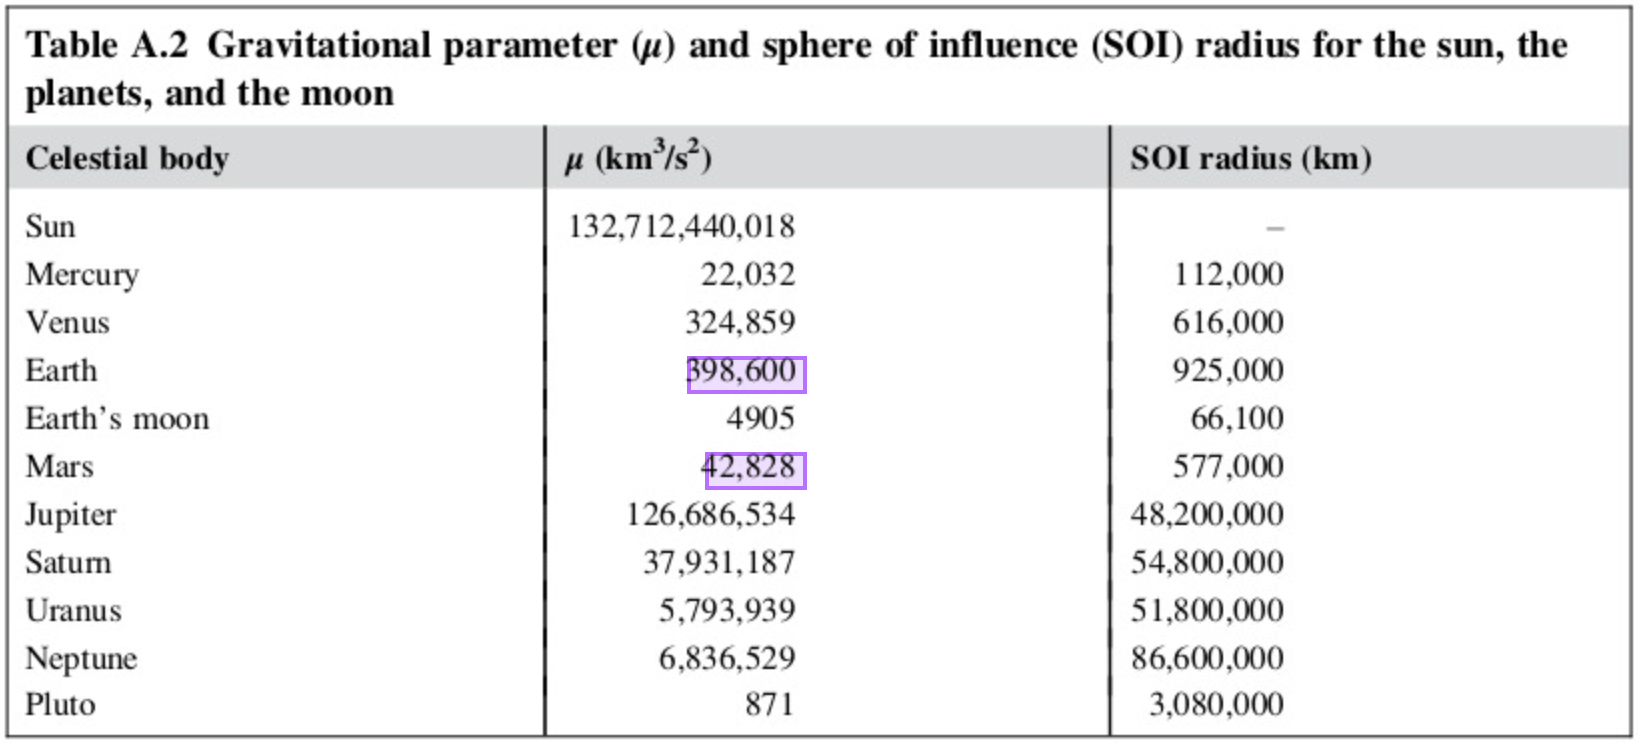

% Constants
mu1 = 398600; % Gravitational parameter for the departure planet (km^3/s^2)
r1 = 149.6*10^6; % Orbital radius of the departure planet (km)
p1 = 200 + 6378; % Parking orbit radius around the departure planet (km)
mu2 = 126686534; % Gravitational parameter for the arrival planet (km^3/s^2)
r2 = 778.6*10^6; % Orbital radius of the arrival planet (km)
p2 = 200 + 71490; % Parking orbit radius around the arrival planet (km)
muSun = 132712441018; % Gravitational parameter for the Sun (km^3/s^2)

% Functions
Vdepart = @(r1, r2) sqrt(muSun/r1)*(sqrt((2*r2)/(r1+r2))-1);
Varrive = @(r1, r2) sqrt(muSun/r2)*(1-sqrt((2*r1)/(r1+r2)));
Vp = @(V, mu, r) sqrt((V^2) + (2*mu)/r);
Vsc = @(mu, r) sqrt(mu/r);

% Calculations
Vd = Vdepart(r1, r2);
Va = Varrive(r1, r2);
Vp1 = Vp(Vd, mu1, r1);
Vp2 = Vp(Va, mu2, r2);
Vsc1 = Vsc(mu1, p1);
Vsc2 = Vsc(mu2, p2);

deltaV1 = Vp1 - Vsc1;
deltaV2 = Vp2 - Vsc2;
deltaVtot = deltaV1 + deltaV2;

% Output results
fprintf('Delta-V for departure (deltaV1): %.2f km/s\n', deltaV1);

Delta-V for departure (deltaV1): 1.01 km/s


fprintf('Delta-V for arrival (deltaV2): %.2f km/s\n', deltaV2);

Delta-V for arrival (deltaV2): -36.37 km/s


fprintf('Total Delta-V (deltaVtot): %.2f km/s\n', deltaVtot);

Total Delta-V (deltaVtot): -35.36 km/s
